Create GF(2^8)

n=8;
str=2^n-1;

al=zeros(1,str);
lt=zeros(1,str);

x=1;

for i=1:str

    if x>str
        x=bitxor(x,285);
    end
    %Indeks 1=0 o.s.v
    al(i)=x;
    lt(x)=i-1;
    x=x*2;
    

end
al

al =      1     2     4     8    16    32    64   128    29    58   116   232   205   135    19    38    76   152    45    90   180   117   234   201   143     3     6    12    24    48    96   192   157    39    78   156    37    74   148    53   106   212   181   119   238   193   159    35    70   140


lt

lt =      0     1    25     2    50    26   198     3   223    51   238    27   104   199    75     4   100   224    14    52   141   239   129    28   193   105   248   200     8    76   113     5   138   101    47   225    36    15    33    53   147   142   218   240    18   130    69    29   181   194


setLogtable(lt);
setAntilog(al);

Receive a message

% Iterations that are tested are 1 to 6
iteration=6;
% Tested error probabilities
xakse=0:0.0025:0.0125;
% Create a plotmatrix, where each column 
% represents an error probability 
%detailPlot=zeros(iteration,length(xakse))
for plotcount=5:length(xakse)
    err=0.0025*(plotcount-1)
    %get the average of ten tests
    for k=1:50
        r=rand(256)<err; % Create a 256x256 matrix with ones/errors at random
        for iter=1:iteration
            %rows
            for i=1:256
                r(i,:)=bch(r(i,:)); % bch(r) is a function that contains our decoder
            end
            %columns
            for i=1:256
                r(:,i)=transpose(bch(transpose(r(:,i))));
            end
            % The error probability after decoding is added to the
            % plotmatrix
            detailPlot(iter,plotcount)=detailPlot(iter,plotcount)+sum(r==1,'all');
        end
    end
save
end

err = 0.0100


Saving to: C:\Users\isabe\OneDrive\Skrivebord\MATLAB\matlab.mat



err = 0.0125

Index exceeds the number of array elements. Index must not exceed 255.

Error in BER>bch (line 134)
result(k-s1log)=1-result(k-s1log);

detailPlot(:,6)=detailPlot(:,6)/18*50

detailPlot = 1.0e+04 *

         0    0.0003    0.0534    0.5243    3.3847    3.1989
         0         0         0    0.0303    1.8517    2.9781
         0         0         0         0    1.0737    2.9275
         0         0         0         0    0.6088    2.9058
         0         0         0         0    0.3579    2.8981
         0         0         0         0    0.2441    2.8953


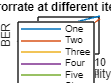

figure
semilogy(xakse(1:6),detailPlot(1,1:6)/(256*256*50));
hold on
semilogy(xakse(1:6),detailPlot(2,1:6)/(256*256*50));
semilogy(xakse(1:6),detailPlot(3,1:6)/(256*256*50));
semilogy(xakse(1:6),detailPlot(4,1:6)/(256*256*50));
semilogy(xakse(1:6),detailPlot(5,1:6)/(256*256*50));
semilogy(xakse(1:6),detailPlot(6,1:6)/(256*256*50));

title("Errorrate at different iterations")
xlabel("Error Probability")
ylabel("BER")

legend('One','Two','Three','Four','Five','Six')

legend show
save


Saving to: C:\Users\isabe\OneDrive\Skrivebord\MATLAB\matlab.mat



semilogy(xakse(1:4),detailPlot(i,1:4), 'DisplayName', ['Row ' num2str(i)])

function setLogtable(x)
global logtable 
logtable=x;
end

function r = getlogtable
global logtable
r = logtable;
end

function setAntilog(x)
global antilog
antilog=x;
end

function r = getantilog
global antilog
r = antilog;
end

Decode a vector

function dec=bch(r)
n=8;
str=2^n-1;
result=r(1:255);
k=length(result);
s1=0;
s3=0;
antilog=getantilog;
logtable=getlogtable;

for i=1:k
    if r(i)==1
      s1=bitxor(s1,antilog((k-i)+1));
    end
end

if s1==0
    s1log=-1;
else
    s1log=logtable(s1);
end



for i=1:k
    if r(i)==1
        s3=bitxor(s3,antilog(mod(k-i*3,str)+1)); %Istedet for modulo større tabel
    end
end

if s3==0
    s3log=-1;
else
    s3log=logtable(s3);
end
if (s1 == 0 && s3 == 0)

result = [result r(256)];
    if mod(sum(result==1),2)~=0
        result(256)=1-result(256);
    end

elseif(mod(3*s1log,str)==s3log) 

       
result(k-s1log)=1-result(k-s1log);
result = [result r(256)];
    if mod(sum(result==1),2)~=0
        result(256)=1-result(256);
    end
%%Hertil korrekt

else 

    sigma1=s1;

    
    if s1==0
        result;
    else

      sigma2=bitxor(antilog(mod(3*s1log,str)+1),s3);
      sigma2=logtable(sigma2)-s1log;

      A=mod(2*s1log,str);
      A=mod(sigma2-A,str);


    
    j=1;
    rod=zeros(1,2);
    %%Skal laves til tabel
    
    aA=antilog(A+1);
    alfa=gf(2,8);


    %%Laves til tabel
    for i=0:k
        if ((alfa^i)^2+alfa^i+gf(aA,8))==0
            rod(j)=i;
            j=j+1;
        end
    end

    rod;

    if j<3
        result;
    else
    
    
    e1=mod(rod(1)+s1log,str);
    e2=mod(rod(2)+s1log,str);


    result(k-e1)=1-result(k-e1);
    result(k-e2)=1-result(k-e2);

    
    end
  

    end

end
if length(result)==255
    result = [result r(256)];
    if mod(sum(result==1),2)==0
    else
        result = r;
    end
end
dec = result;
end

